# ASS 1

Vladislav Serafimov  509761

Stephen Cruz Wright 521476

## 1. Sampling

### 1.1 Sampled time

t = 0:1/1600:2;

**What is the maximum frequency which can be present in a continuous signal such that the original signal can be reconstructed again from the sampled signal?**

Using the formula $f_{sampled} \leq 2f$ we can determine that the maximum frequency of the function is 800Hz

### 1.2 Sampled signal

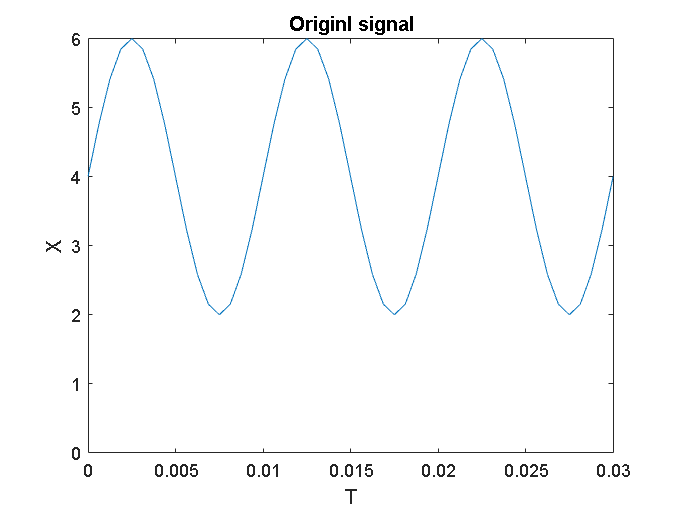

y = 4 + 2*sin(2*pi*100*t);

plot(t,y)
title("Originl signal")
ylabel("X")
xlabel("T")
axis ([0 0.03 0 6])

figure


### 1.3 Plot the sampled signal

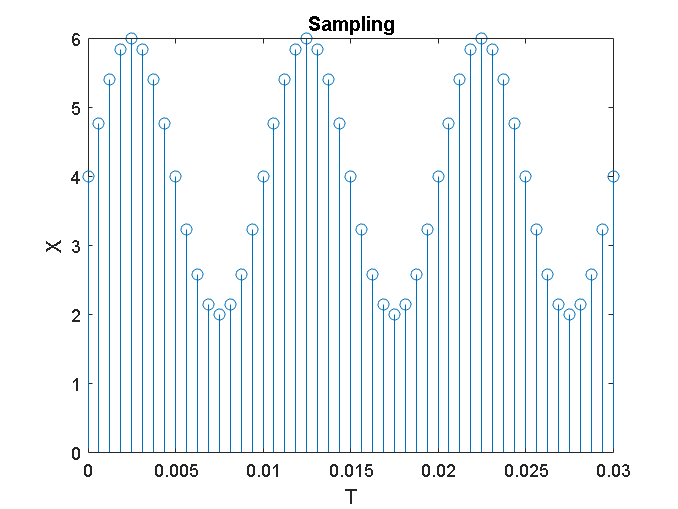

stem(t,y)
title("Sampling")
ylabel("X")
xlabel("T")
axis ([0 0.03 0 6])

figure


## 2. Frequency Spectrum

### 2.1 Ignition

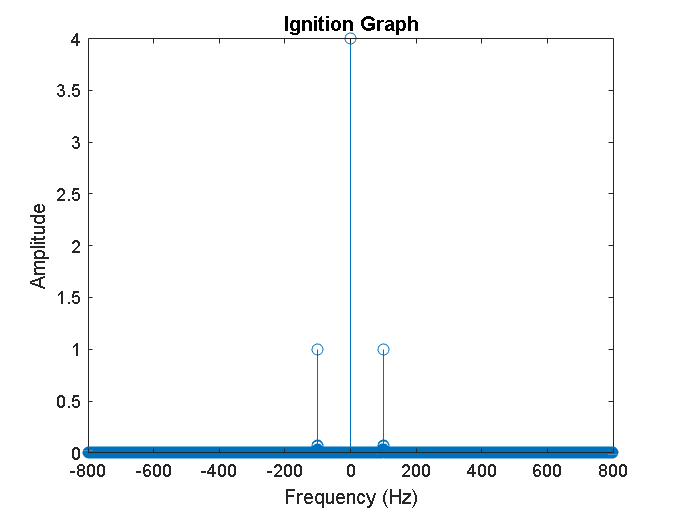

clear
t = 0:1/1600:2;

y = 4 + 2*sin(2*pi*100*t);
ypp = fftshift(fft(y) / length(y));
yp = (1600 / length(y)) * (-length(y)/2:length(y)/2 - 1);

stem(yp,abs(ypp))
title("Ignition Graph")
ylabel("Amplitude")
xlabel("Frequency (Hz)")

figure

### 2.2 Double trouble

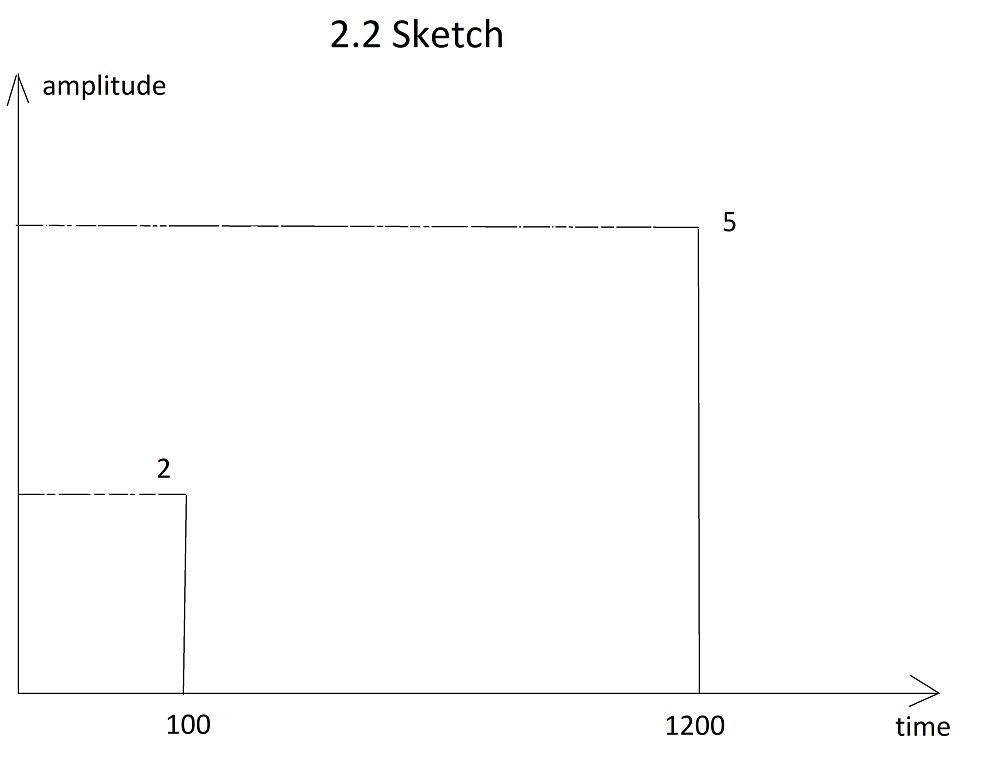

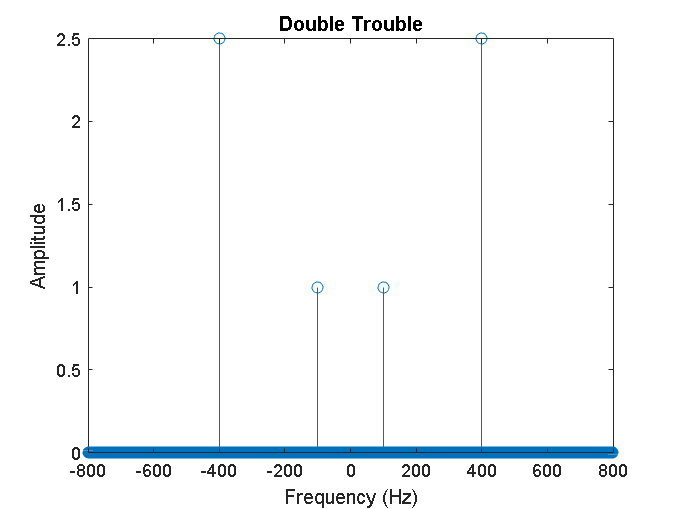

clear
t = 0:1/1600:2 - 1/1600;
y = + 2.*sin(2.*pi.*100.*t) + 5.*cos(2.*pi.*1200.*t);

ypp = fftshift(fft(y) / length(y));
yp = (1600 / length(y)) * (-length(y)/2:length(y)/2 - 1);

stem(yp,abs(ypp))
title("Double Trouble")
ylabel("Amplitude")
xlabel("Frequency (Hz)")

figure

### 2.3 Square wave

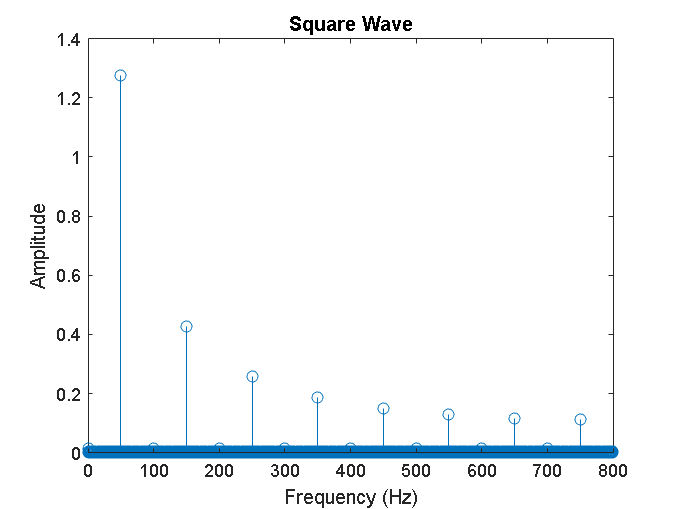

t = 0:1/1600:10 - 1/1600;

y = 2.*square(2.*pi.*50.*t);
ypp = abs(fftshift(fft(y) / length(y)));
yp = (1600 / length(y)) * (-length(y)/2:length(y)/2 - 1);

stem(yp,ypp)
title("Square Wave")
ylabel("Amplitude")
xlabel("Frequency (Hz)")
xlim([0 800])

figure

the reason why we chose a sampling frequency of 1/100 is because the value should be $\frac{1}{2f}$ when frequency is 50Hz

we observe that the square wave has odd harmonics and the predominant frequency .